# Proyecto métodos numéricos

## Perfil cinemático del eje

clear
syms a1(t) a2(t) a3(t) a4(t) a5(t)  T A
syms v1(t) v2(t) v3(t) v4(t) v5(t)  
syms x1(t) x2(t) x3(t) x4(t) x5(t) 
assume(T>0)
assume(A>0)

A=50;


## Aceleración

a1(t)=3*A/T*t;
a2(t)=A;
a3(t)=-3*A/T*t;
Ca3=A-a3(2*T/3);
a3(t)=a3(t)+Ca3;
a4(t)=0;
fprintf('Función de aceleración:')

Función de aceleración:

aceleracion(t)=piecewise((0<=t<T/3),a1,(T/3<=t<2*T/3),a2,(2*T/3<=t<T),a3,(T<=t),a4)

$$aceleracion(t) = \left\{ \begin{array}{cl} \frac{150\,t}{T} & \text{ if }3\,t<T\wedge 0\leq t\\ 50 & \text{ if }T\leq 3\,t\wedge 3\,t<2\,T\\ 150-\frac{150\,t}{T} & \text{ if }t<T\wedge 2\,T\leq 3\,t\\ 0 & \text{ if }T\leq t \end{array}\right.$$

## Velocidad


v1(t)=int(a1);

v2(t)=int(a2);
Cv2=v1(T/3)-v2(T/3);
v2(t)=v2(t)+Cv2;

v3(t)=int(a3);
Cv3=v2(2*T/3)-v3(2*T/3);
v3(t)=v3(t)+Cv3;

v4(t)=int(a4)

$$v4(t) = 0$$

Cv4=v3(T)-v4(T)

$$Cv4 = \frac{100\,T}{3}$$

v4(t)=v4(t)+Cv4

$$v4(t) = \frac{100\,T}{3}$$


fprintf('Función de velocidad:')

Función de velocidad:

velocidad(t)=piecewise((0<=t<T/3),v1,(T/3<=t<2*T/3),v2,(2*T/3<=t<T),v3,(t>=T),v4)

$$velocidad(t) = \left\{ \begin{array}{cl} \frac{75\,t^{2}}{T} & \text{ if }3\,t<T\wedge 0\leq t\\ 50\,t-\frac{25\,T}{3} & \text{ if }T\leq 3\,t\wedge 3\,t<2\,T\\ 150\,t-\frac{125\,T}{3}-\frac{75\,t^{2}}{T} & \text{ if }t<T\wedge 2\,T\leq 3\,t\\ \frac{100\,T}{3} & \text{ if }T\leq t \end{array}\right.$$

## Desplazamiento


z1(t)=int(v1);

z2(t)=int(v2);
Cz2=z1(T/3)-z2(T/3);
z2(t)=z2(t)+Cz2;

z3(t)=int(v3);
Cz3=z2(2*T/3)-z3(2*T/3);
z3(t)=z3(t)+Cz3;

z4(t)=int(v4);
Cz4=z3(T)-z4(T);
z4(t)=z4(t)+Cz4;

fprintf('Función de desplazamiento:')

Función de desplazamiento:

posicion(t)=piecewise((0<=t<T/3),z1,(T/3<=t<2*T/3),z2,(2*T/3<=t<T),z3,(t>=T),z4)

$$posicion(t) = \begin{array}{l} \left\{ \begin{array}{cl} \sigma_{1} & \text{ if }3\,t<T\wedge 0\leq t\\ \frac{25\,T^{2}}{27}-\frac{25\,t\,\left(T-3\,t\right)}{3} & \text{ if }T\leq 3\,t\wedge 3\,t<2\,T\\ \frac{25\,T^{2}}{3}-\frac{125\,T\,t}{3}+75\,t^{2}-\sigma_{1} & \text{ if }t<T\wedge 2\,T\leq 3\,t\\ \frac{100\,T\,t}{3}-\frac{50\,T^{2}}{3} & \text{ if }T\leq t \end{array}\right.\\ \mathrm{where}\\ \sigma_{1}=\frac{25\,t^{3}}{T} \end{array}$$

## Solución de tMax

f=2*pi==posicion(T)

$$f = 2\,\pi =\frac{50\,T^{2}}{3}$$


Tgiro=solve(f,T)

$$Tgiro = \frac{\sqrt{3}\,\sqrt{\pi }}{5}$$

double(Tgiro)

ans = 0.6140


aceleracion=subs(aceleracion,T,Tgiro);
velocidad=subs(velocidad,T,Tgiro);
posicion=subs(posicion,T,Tgiro)

$$posicion(t) = \begin{array}{l} \left\{ \begin{array}{cl} \sigma_{2} & \text{ if }t\in \left[0,\sigma_{4}\right)\\ \frac{\pi }{9}+\frac{25\,t\,\left(3\,t-\sigma_{1}\right)}{3} & \text{ if }t\in \left[\sigma_{4},\sigma_{3}\right)\\ -\sigma_{2}+75\,t^{2}-\frac{25\,\sqrt{3}\,\sqrt{\pi }\,t}{3}+\pi & \text{ if }t\in \left[\sigma_{3},\sigma_{1}\right)\\ \frac{20\,\sqrt{3}\,t\,\sqrt{\pi }}{3}-2\,\pi & \text{ if }\sigma_{1}\leq t \end{array}\right.\\ \mathrm{where}\\ \sigma_{1}=\frac{\sqrt{3}\,\sqrt{\pi }}{5}\\ \sigma_{2}=\frac{125\,\sqrt{3}\,t^{3}}{3\,\sqrt{\pi }}\\ \sigma_{3}=\frac{2\,\sqrt{3}\,\sqrt{\pi }}{15}\\ \sigma_{4}=\frac{\sqrt{3}\,\sqrt{\pi }}{15} \end{array}$$



fprintf('Tiempo de primera vuelta %.3f s',Tgiro)

Tiempo de primera vuelta 0.614 s

## Gráficas


ts=linspace(0,2*Tgiro,200);

Vmax=double(velocidad(Tgiro))

Vmax = 20.4665

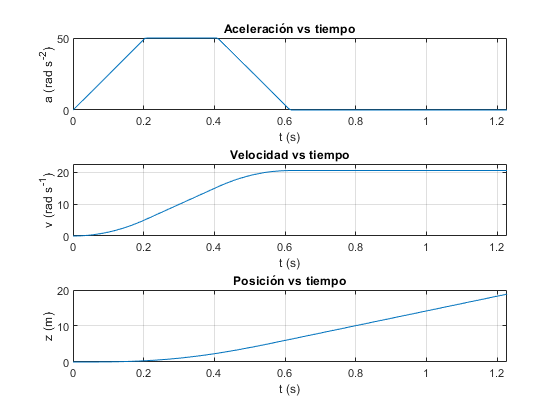

subplot(3,1,1)
plot(ts,aceleracion(ts))
title('Aceleración vs tiempo')
grid on
xlabel('t (s)')
ylabel('a (rad s^{-2})')
xlim([0 double(2*Tgiro)])

subplot(3,1,2)
plot(ts,velocidad(ts))
title('Velocidad vs tiempo')
grid on
xlabel('t (s)')
ylabel('v (rad s^{-1})')
ylim([0 Vmax*1.1])
xlim([0 double(2*Tgiro)])

subplot(3,1,3)
plot(ts,posicion(ts))
title('Posición vs tiempo')
grid on
xlabel('t (s)')
ylabel('z (m)')
xlim([0 double(2*Tgiro)])



TablaCinematica=table(double(ts)',double(aceleracion(ts))',double(velocidad(ts))',double(posicion(ts))');
TablaCinematica.Properties.VariableNames=["Tiempo","Aceleración","Velocidad","Posición"]

TablaCinematica = 200×4 table
     Tiempo      Aceleración    Velocidad     Posición 
    _________    ___________    _________    __________

            0           0               0             0
    0.0061708      1.5075       0.0046514    9.5676e-06
     0.012342      3.0151        0.018605    7.6541e-05
     0.018512      4.5226        0.041862    0.00025832
     0.024683      6.0302        0.074422    0.00061232
     0.030854      7.5377         0.11628     0.0011959
     0.037025      9.0452         0.16745     0.0020666
     0.043196      10.553         0.22792     0.0032817
     0.049367       12.06         0.29769     0.0048986
     0.055537      13.568         0.37676     0.0069748
     0.061708      15.075         0.46514     0.0095676
     0.067879      16.583         0.56282      0.012734
      0.07405       18.09          0.6698      0.


%TablaTXT=table(double(ts)',double(velocidad(ts))');
%writetable(TablaTXT,'Perfil_Velocidad.txt','delimiter',' ', 'WriteVariableNames', false)
clearvars -except Tgiro posicion aceleracion velocidad TablaCinematica

## Solución analítica

### Resolución de cadena cinemática

## Solución por métodos numéricos

AB+BC+CA=0

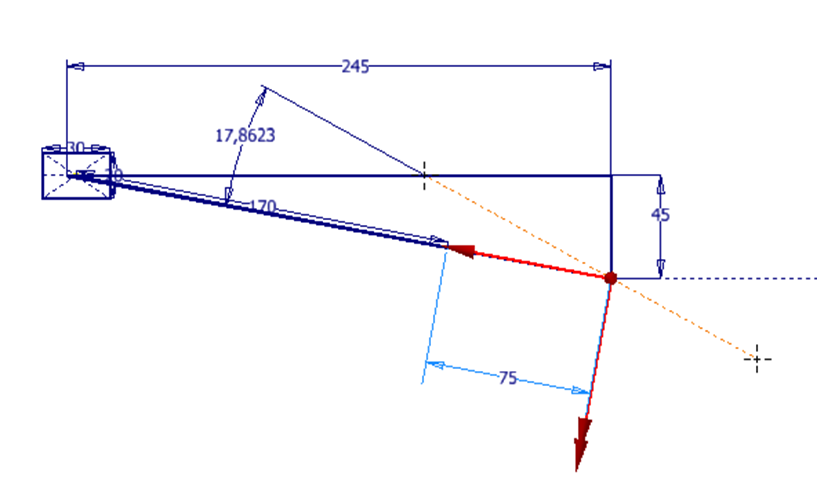

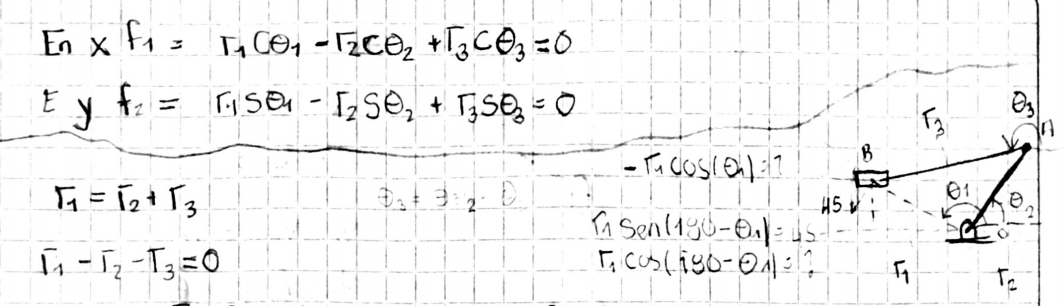


syms t Theta_1(t) Theta_2(t) Theta_3(t) R_1(t)

syms r_1 r_2 r_3 x

syms V_r omega_1 omega_2 omega_3 theta_1 theta_2 theta_3 
theta_2i=30*sym(pi)/180

$$theta\_2i = \frac{\pi }{6}$$

Vr_2=0.75

Vr_2 = 0.7500

Vr_3=1.70

Vr_3 = 1.7000

Vomega_2=20

Vomega_2 = 20


Fc=sin(Theta_1)*R_1-0.45;
Fc=simplify(Fc,'Steps',5);

fc=subs(Fc,[Theta_1, R_1],[theta_1, r_1]);
SolR_1=solve(fc,r_1)

$$SolR\_1 = \frac{9}{20\,\sin\left(\theta_{1}\right)}$$



Fx=-R_1*cos(Theta_1)+r_2*cos(Theta_2)+r_3*cos(Theta_3);
Fx=simplify(Fx,'Steps',5);

fx=formula(subs(Fx,[Theta_1, Theta_2, Theta_3, R_1],[theta_1, theta_2, theta_3, SolR_1]));
fx=simplify(fx,'Steps',5)

$$fx = r_{2}\,\cos\left(\theta_{2}\right)-\frac{9\,\cot\left(\theta_{1}\right)}{20}+r_{3}\,\cos\left(\theta_{3}\right)$$

SolTheta_1=solve(fx,theta_1)

$$SolTheta\_1 = \mathrm{acot}\left(\frac{20\,r_{2}\,\cos\left(\theta_{2}\right)}{9}+\frac{20\,r_{3}\,\cos\left(\theta_{3}\right)}{9}\right)$$



Fy=R_1*sin(Theta_1)-r_2*sin(Theta_2)-r_3*sin(Theta_3);
Fy=simplify(Fy,'Steps',5);

fy=formula(subs(Fy,[Theta_1, Theta_2, Theta_3, R_1],[theta_1, theta_2, theta_3, SolR_1]))

$$fy = \frac{9}{20}-r_{3}\,\sin\left(\theta_{3}\right)-r_{2}\,\sin\left(\theta_{2}\right)$$


SolTheta_3=solve(fy,theta_3);
SolTheta_3=SolTheta_3(1)

$$SolTheta\_3 = -\mathrm{asin}\left(\frac{r_{2}\,\sin\left(\theta_{2}\right)-\frac{9}{20}}{r_{3}}\right)$$





DFcDt=diff(Fc)

$$DFcDt(t) = \sin\left(\Theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}R_{1}\left(t\right)+\cos\left(\Theta_{1}\left(t\right)\right)\,R_{1}\left(t\right)\,\frac{\partial }{\partial t}\Theta_{1}\left(t\right)$$

DFxDt=diff(Fx)

$$DFxDt(t) = \sin\left(\Theta_{1}\left(t\right)\right)\,R_{1}\left(t\right)\,\frac{\partial }{\partial t}\Theta_{1}\left(t\right)-\cos\left(\Theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}R_{1}\left(t\right)-r_{2}\,\sin\left(\Theta_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}\Theta_{2}\left(t\right)-r_{3}\,\sin\left(\Theta_{3}\left(t\right)\right)\,\frac{\partial }{\partial t}\Theta_{3}\left(t\right)$$

DFyDt=diff(Fy)

$$DFyDt(t) = \sin\left(\Theta_{1}\left(t\right)\right)\,\frac{\partial }{\partial t}R_{1}\left(t\right)-r_{2}\,\cos\left(\Theta_{2}\left(t\right)\right)\,\frac{\partial }{\partial t}\Theta_{2}\left(t\right)-r_{3}\,\cos\left(\Theta_{3}\left(t\right)\right)\,\frac{\partial }{\partial t}\Theta_{3}\left(t\right)+\cos\left(\Theta_{1}\left(t\right)\right)\,R_{1}\left(t\right)\,\frac{\partial }{\partial t}\Theta_{1}\left(t\right)$$


F1=formula(subs(DFxDt,[diff(R_1),diff(Theta_1),diff(Theta_2),diff(Theta_3),Theta_1,Theta_2,Theta_3,R_1],[V_r,omega_1,omega_2,omega_3,theta_1,theta_2,theta_3,r_1]))

$$F1 = \omega_{1}\,r_{1}\,\sin\left(\theta_{1}\right)-V_{r}\,\cos\left(\theta_{1}\right)-\omega_{2}\,r_{2}\,\sin\left(\theta_{2}\right)-\omega_{3}\,r_{3}\,\sin\left(\theta_{3}\right)$$

F2=formula(subs(DFyDt,[diff(R_1),diff(Theta_1),diff(Theta_2),diff(Theta_3),Theta_1,Theta_2,Theta_3,R_1],[V_r,omega_1,omega_2,omega_3,theta_1,theta_2,theta_3,r_1]))

$$F2 = V_{r}\,\sin\left(\theta_{1}\right)+\omega_{1}\,r_{1}\,\cos\left(\theta_{1}\right)-\omega_{2}\,r_{2}\,\cos\left(\theta_{2}\right)-\omega_{3}\,r_{3}\,\cos\left(\theta_{3}\right)$$

F3=formula(subs(DFcDt,[diff(R_1),diff(Theta_1),diff(Theta_2),diff(Theta_3),Theta_1,Theta_2,Theta_3,R_1],[V_r,omega_1,omega_2,omega_3,theta_1,theta_2,theta_3,r_1]))

$$F3 = V_{r}\,\sin\left(\theta_{1}\right)+\omega_{1}\,r_{1}\,\cos\left(\theta_{1}\right)$$

iteraciones=9;
f(V_r,omega_1,omega_3)=[F1;F2;F3]

$$f(V\_r, omega\_1, omega\_3) = \left(\begin{array}{c} \omega_{1}\,r_{1}\,\sin\left(\theta_{1}\right)-V_{r}\,\cos\left(\theta_{1}\right)-\omega_{2}\,r_{2}\,\sin\left(\theta_{2}\right)-\omega_{3}\,r_{3}\,\sin\left(\theta_{3}\right)\\ V_{r}\,\sin\left(\theta_{1}\right)+\omega_{1}\,r_{1}\,\cos\left(\theta_{1}\right)-\omega_{2}\,r_{2}\,\cos\left(\theta_{2}\right)-\omega_{3}\,r_{3}\,\cos\left(\theta_{3}\right)\\ V_{r}\,\sin\left(\theta_{1}\right)+\omega_{1}\,r_{1}\,\cos\left(\theta_{1}\right) \end{array}\right)$$

f=subs(f,r_1,SolR_1);
f=subs(f,theta_1,SolTheta_1);
f=subs(f,theta_3,SolTheta_3);
f=subs(f,[theta_2,r_2,r_3,omega_2],[theta_2i,Vr_2,Vr_3,Vomega_2]);
f=simplify(f,'Steps',5)

$$f(V\_r, omega\_1, omega\_3) = \begin{array}{l} \left(\begin{array}{c} \frac{9\,\omega_{1}}{20}-\frac{3\,\omega_{3}}{40}-\frac{\sqrt{11910310}\,V_{r}\,\sqrt{243\,\sqrt{13845}+430939}}{2382062}-\frac{15}{2}\\ \frac{3\,\sqrt{3}\,\omega_{1}}{8}+\frac{\sqrt{4615}\,\omega_{1}}{40}-\frac{\sqrt{4615}\,\omega_{3}}{40}-\frac{15\,\sqrt{3}}{2}-\sigma_{1}\\ \frac{3\,\sqrt{3}\,\omega_{1}}{8}+\frac{\sqrt{4615}\,\omega_{1}}{40}-\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{9\,V_{r}\,\sqrt{243\,\sqrt{13845}+430939}\,\left(3\,\sqrt{35730930}-\sqrt{2198643226}\right)}{938532428} \end{array}$$


Jac=jacobian(f, [V_r,omega_1,omega_3]);
JacInv=Jac^-1;
p1=[1 1 1]'

x1 =      1
     1
     1


ValoresNR(1,:)=p1';

ValoresNR =      1     1     1


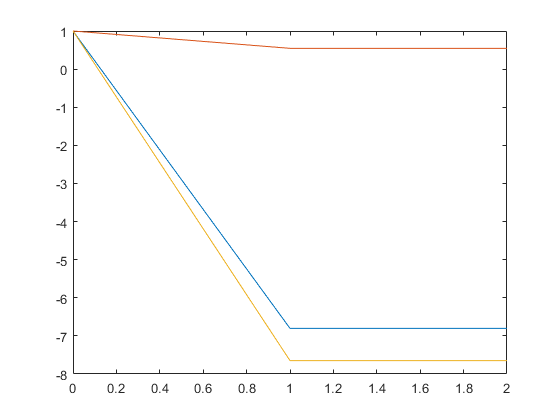

for i=1:iteraciones
    p1=p1-JacInv(p1(1),p1(2),p1(3))*f(p1(1),p1(2),p1(3));
    ValoresNR(i+1,:)=double(p1)';
    ErrorNR(i,:)=abs(ValoresNR(i,:)-ValoresNR(i+1,:));
    NormErrorNR(i)=norm(ErrorNR(i,:));
     if NormErrorNR(i)<0.001
        break;
    end
end

figure()
plot(0:(length(ValoresNR)-1),ValoresNR)

F1=subs(F1,r_1,SolR_1);

F1=subs(F1,theta_1,SolTheta_1);

F1=subs(F1,theta_3,SolTheta_3);

F1=simplify(F1,'Steps',15)

F1=subs(F1,[theta_2,r_2,r_3],[theta_2i,Vr_2,Vr_3])

F2=subs(F2,r_1,SolR_1);

F2=subs(F2,theta_1,SolTheta_1);

F2=subs(F2,theta_3,SolTheta_3);

F2=simplify(F2,'Steps',15)

F2=subs(F2,[theta_2,r_2,r_3],[theta_2i,Vr_2,Vr_3])

F3=subs(F3,r_1,SolR_1);

F3=subs(F3,theta_1,SolTheta_1);

F3=subs(F3,theta_3,SolTheta_3);

F3=simplify(F3,'Steps',15)

F3=subs(F3,[theta_2,r_2,r_3],[theta_2i,Vr_2,Vr_3])


%F1=Fx==0;
%SolTheta_1=solve(F1,Theta_1)

%SolTheta_1=subs(SolTheta_1,theta_2,Theta_2)


Fy=R_1*sin(Theta_1)-r_2*sin(Theta_2)-r_3*sin(Theta_3);
Fy=simplify(Fy,'Steps',5)

$$Fy(t) = \sin\left(\Theta_{1}\left(t\right)\right)\,R_{1}\left(t\right)-r_{3}\,\sin\left(\Theta_{3}\left(t\right)\right)-r_{2}\,\sin\left(\Theta_{2}\left(t\right)\right)$$

F2=Fy==0;

SolTheta_3=solve(Fy,Theta_3);

SolTheta_3=SolTheta_3(1)

SolTheta_3 = struct with fields:
    r_2: [0×1 sym]
      t: [0×1 sym]


Theta_2=theta_2i

$$Theta\_2 = \frac{\pi }{6}$$


Vr_2=0.75

Vr_2 = 0.7500

Vr_3=1.70

Vr_3 = 1.7000




FNR1(Theta_1,Theta_3)=Fx

Error using symfun/subsindex (line 155)
Indexing values must be positive integers, logicals, or symbolic variables.

Error in sym/privsubsasgn (line 1128)
                L_tilde2 = builtin('subsasgn',L_tilde,struct('type','()','subs',{varargin}),R_tilde);

Error in 

FNR2(Theta_1,Theta_3)=Fy


iteraciones=100;
Pi=[0.5 2.2]';

F(Theta_1,Theta_3)=[FNR1;FNR2]

%subs(F,[r_1 r_2 r_3],[])


Jac=jacobian(F, [Theta_1,Theta_3])
JacInv=Jac^-1

ValoresNR(1,:)=Pi';
for i=1:iteraciones
    Pi=Pi-JacInv(Pi(1),Pi(2))*F(Pi(1),Pi(2));
    ValoresNR(i+1,:)=Pi';
    ErrorNR(i,:)=abs(ValoresNR(i,:)-ValoresNR(i+1,:));
    NormErrorNR(i)=norm(ErrorNR(i,:));
    if NormErrorNR(i)<0.001
        break;
    end
end

ValoresNR
NormErrorNR'
plot(0:(length(ValoresNR)-1),ValoresNR)
title('Solución método de Newton Raphson')
legend('x','y')
ylabel('Solución')
xlabel('Indice')
xticks(0:length(ValoresNR))
grid on
plot(ErrorNR)
title('Error absoluto método de Newton Raphson')
legend('E_x','E_y')
ylabel('Error')
xlabel('Iteraciones')
xticks(1:(length(ValoresNR)-1))
grid on

plot(NormErrorNR)
title('Error total método de Newton Raphson')
xlabel('Iteraciones')
xticks(1:(length(ValoresNR)-1))
grid on

SolNR=double(Pi)
ErrorNRFinal=double(NormErrorNR(end))
